**Wstęp**

Podczas 9 laboratoriów dostałem pod analizę sygnał, który został przeze mnie zinterpretowany jako odpowiedź skokowa układu intercyjnego pierwszego lub drugiego rzędu. Moim zadaniem było odpowiednie przefiltrowanie sygnału i dobranie takich parametrów jak okres próbkowania , opóźnienie oraz wzmocnienie, dla których odpowiedź będzie jak najbardziej zbliżona do szukanej przeze mnie na tych. W tym celu użyłem metody nazywanej Identyfikacją, która pozwoliła mi w sposób jak najdokładniejszy wykonać zadanie

**Rysowanie wykresu**

Jako pierwsza część zadania wczytałem obiekt jako plik mat do skryptu, a następnie za pośrednictwem funkcji plot wyrysowałem wykres tej funkcji.

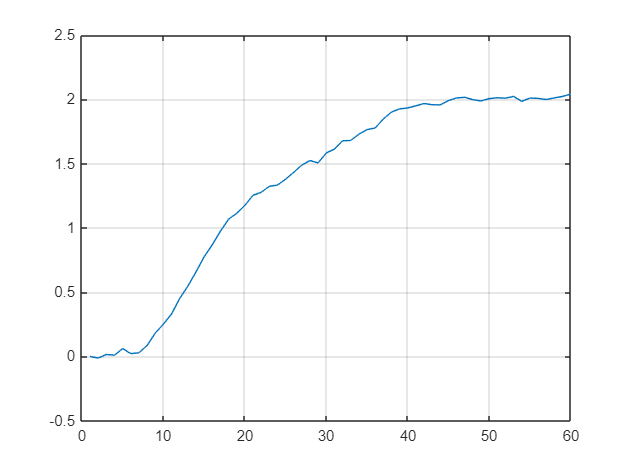

load obiekt
global y 

plot(y) 
grid on

Zgodnie z zapowiedziami wykres zawiera wiele "szumów" - zakłóceń, które uniemożliwiają jego głębszą analizę. Jednak już teraz mogę stwierdzić że jest to układ inercyjny pierwszego lub drugiego rzędu z opóźnieniem.

**Predykowanie transmitancji**

Zacząłem swoje zmaganie od przybliżenia wykresu obiektem inercyjnym pierwszego rzędu. Zacząłem od wyrysowania go metodą pade'a. Nie jest ona jednak zbyt dokładna, ponieważ wprowadza dodatkowe zniekształcenia szczególnie na początku przez co trzeba go bardziej przybliżać. Wydłuża to oczywiście czas obliczeń. Do dalszych obliczeń używałem docelowej metody a Pade'a umieszczam tylko w ramach ciekawostki.

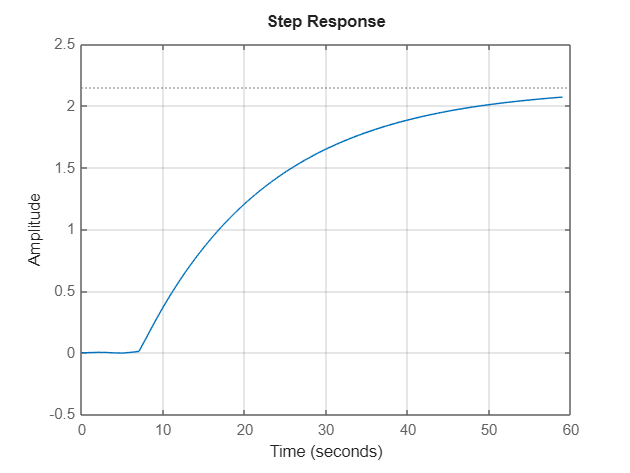

[licz_op,mian_op] = pade(theta,15);
licz_iner = [0, k];
mian_iner = [T, 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
A1 = tf(licz, mian);
t = 0:59;
step(A1,t);
axis([0,60,-0.5,2.5]);
grid on

Na wykresie widać dosyć dobre przybliżenie naszego zaszumionego wykresu jednak do porządnego porównania użyłem już następnej metody która towarzyszyła mi do końca ćwiczenia.

**Metoda zaproponowana na zajęciach**

Faktyczną metodę jaką użyłem było po prostu użycie funkcji tf z bardziej zaawansowanymi jej ustawieniami, gdzie wprowadzałem również poza licznikiem i mianownikiem transmitancji również człon opóźniający. Ustawiłem czas tak aby widzieć przez 60 sekund jak się zmienia odpowiedź układu na skok jednostkowy. Uzyskany obiekt A poddałem reakcji na skok, a następnie na wykresie porównałem zanieczyszczony sygnał z uzyskanym.

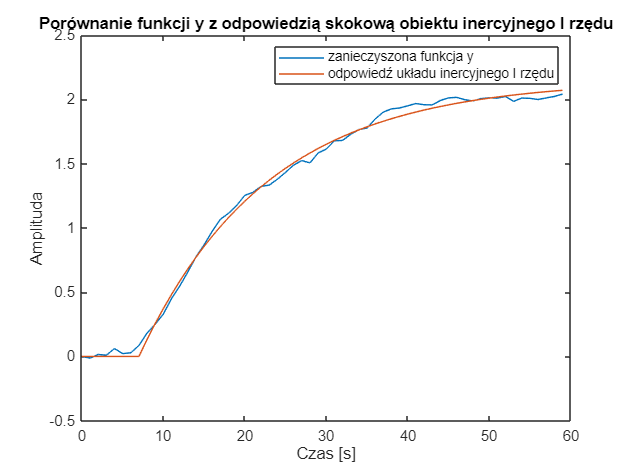

theta = 7;
k = 2.15;
T = 15.75;
A = tf([0,k], [T,1], 'OutputDelay', theta);
t = 0:59;
yA = step(A,t);
plot(t,y,t,yA);
title("Porównanie funkcji y z odpowiedzią skokową obiektu inercyjnego I rzędu")
xlabel("Czas [s]")
ylabel("Amplituda")
legend("zanieczyszona funkcja y", "odpowiedź układu inercyjnego I rzędu")

W tym miejscu wyliczaliśmy błąd uzyskanej funkcji względem analizowanej. Metodą prób okazało się, że MSE jest najmniejsze dla  theta = 7, k = 2.15, T = 15.75 i wynosi 0.0015. Na wykresie widać, że przy tak dobranych parametrach moja funkcja bardzo dokładnie przybliża zachowanie szukanej funkcji.

e = y - yA;
MSE = sum(e.^2) / length(e)

MSE = 0.0015

**Fminsearch -dla układu inercyjnego I rzędu**

Istnieje jednak dużo prostsza metoda, którą można łatwo wykorzystywać budując wiele różnych obiektów charakteryzujących się innymi odpowiedziami na skok. Na zajęciach skorzystałem z funkcji fminsearch, która szuka dobiera parametry w taki sposób aby błąd MSE był jak najmniejszy. Jako drugi argument fminsearch przyjmuje funkcję na przestrzeni, której mają być zmieniane parametry. I tak włożyłem moje wyszukane parametry na zajęciach dla których błąd jest najmniejszy i uzyskałem zarówno jeszcze dokładniejsze parametry jak i jeszcze dokładniejszą, lepiej dopasowaną odpowiedź układu inercyjnego na skok. Odpowiednio uzupełniona funkcja ident znajduje się na końcu sprawozdania.

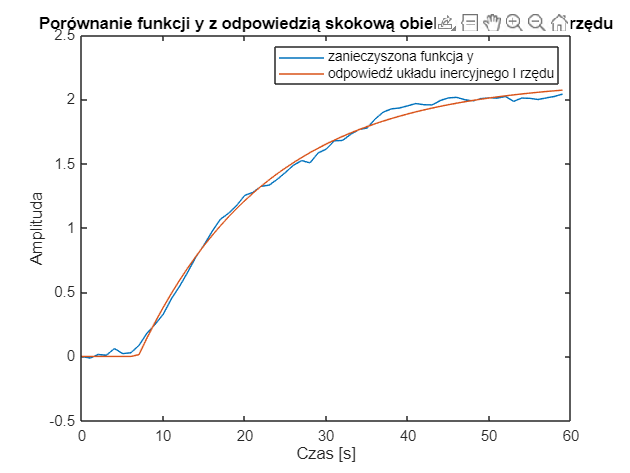

parametry =     2.1516   15.8017    6.8954


blad = 0.0015

[parametry, blad] = fminsearch('ident',[k,T,theta])

Błąd okazał się wyświetlić taki sam, ale to dlatego, że wartości były już na tyle dokładnie dobrane, że nie potrzeba było ich znacznie modyfikować i wykres został nie wiele zmieniony w stosunku do wersji poprzedniej.

**Fminsearch - dla układu inercyjnego II rzędu**

Jako kolejny układ poddałem analiznie inercyjny drugiego rzędu. W tym celu poczyniłem kroki jak w poprzedniej części modyfikując jednak nieco funkcję ident nazywając ją i zapisując do mpliku ident2. Tym razem pakowałem do niej 4 modyfikowalne argumenty a to dlatego, że pojawiają mi się dwie stałe czasowe T1 oraz T2. Tym samym zmienia mi się wzór na transmitancję obiektu. Jako T1 wkładam do funkcji T, a jako T2 1. Uzupełnioną funkcję ident2 umieściłem na końcu sprawozdania

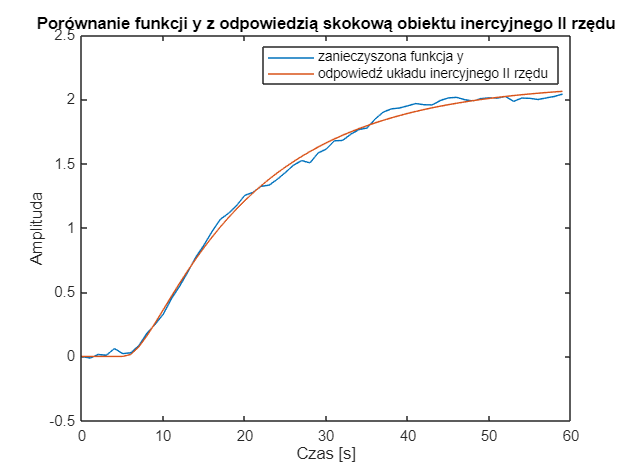

parametry_1 =     2.1292   14.8404    2.0541    5.2836


blad_1 = 0.0013

theta = 7;
k = 2.15;
T = 15.75;
[parametry_1, blad_1] = fminsearch('ident2',[k,T,1,theta])

Co ciekawe okazuje się, że po dobraniu dokładnych parametrów przez funkcję fminsearch błąd się zmniejszył względem obiektu inercyjnego pierwszego rzędu. Oznacza to prawdopodobnie, że sygnał pochodził od odpowiedzi układu skokowego układu inercyjnego pierwszego rzędu. Na tą dokładność wskazuje również wykres, który jest idealnie dopasowany do zaszumionego sygnału.

**Fminsearch - dla obiektu wieloinercyjnego bez opóźnienia**

Odpowiedź skokowa obiektu wieloinercyjnego bez opóźnienia, cechuje się łagodnym startem bez, więc mogła ona być również źródłem zaszumionego sygnału. Testowałem odpowiedzi dla różnych wartości n jednak w zakresie [3,5], ponieważ np. testowanie obiektu z n = 6 jest kompletnie pozbawione sensu gdyż odpowiedź będzie cechowała się bardzo stromym startem co nie jest charakter    ystyczne dla analizowanego wykresu. Wykonuje te same kroki co poprzednio oczywiście odpowiednio modyfikując mplik ident1 gdzie zdefiniowałem transmitancję obiektu wieloinercyjnego bez opóźnienia. Funkcję ident1 umieściłem na końcu sprawozdania. Dodatkowo ustawiłem n jako zmienną globalną aby modyfikwać ją według potrzeb w livescripcie.

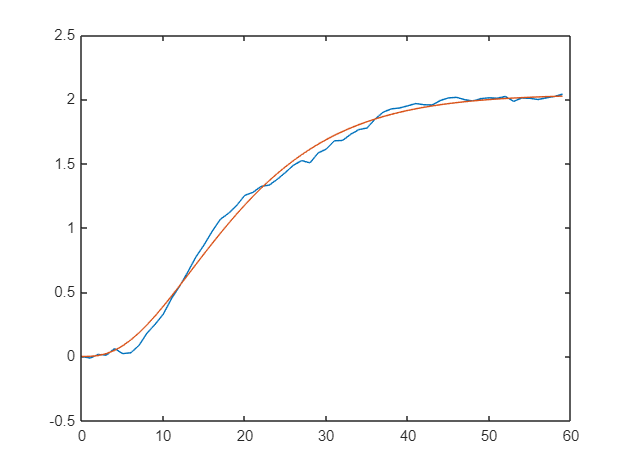

parametry1 =     2.0396    6.6553


blad1 = 0.0024

global n 
n = 3;
[parametry1, blad1] = fminsearch('ident1',[k,T])

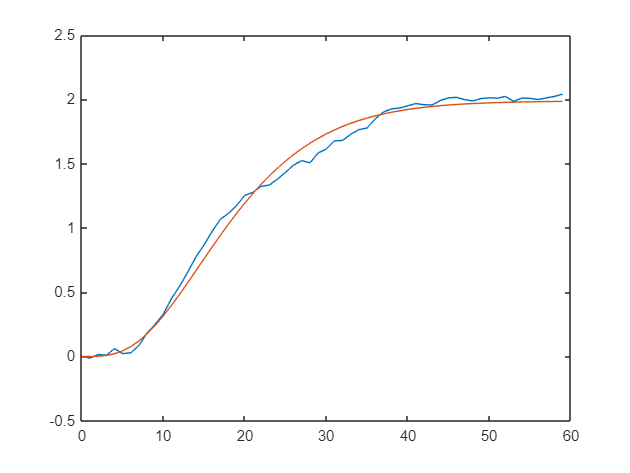

parametry2 =     1.9880    4.7882


blad2 = 0.0040

n = 4;
[parametry2, blad2] = fminsearch('ident1',[k,T])

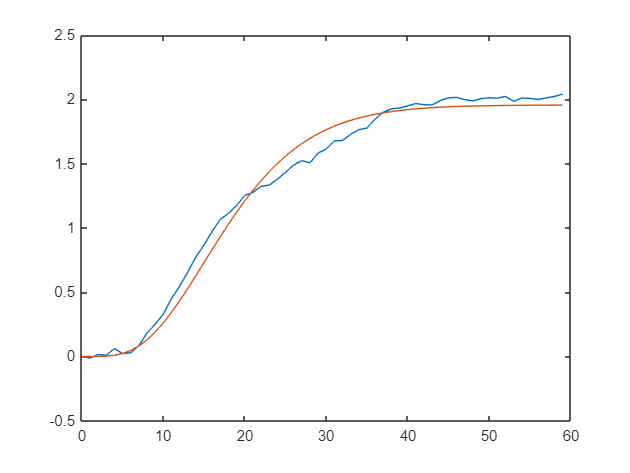

parametry3 =     1.9567    3.7380


blad3 = 0.0071

n = 5;
[parametry3, blad3] = fminsearch('ident1',[k,T])

Po przeanalizowaniu wykresów widać że w miarę zwiększania wartości n wykres staje się mniej dokładny i ciężej go programowo dopasować do sygnału. W związku z tym najlepiej wypada obiekt z n = 3. Reszta ma większe błędy i nie mogłaby stanowić odpowiedzi takiej jak zaszumiony sygnał

**Podsumowanie**

Przeprowadzona analiza pozwoliła na skuteczną identyfikację parametrów odpowiedzi skokowej zaszumionego sygnału.  Wykres odpowiedzi skokowej układu inercyjnego pierwszego rzędu był bardzo dokładnie dopasowany do analizowanego sygnału. Następnie, w przypadku układu inercyjnego drugiego rzędu, zastosowałem bardziej zaawansowany model z dodatkowymi parametrami T1 i T2. Dalsze zmniejszenie błędu oraz lepsze dopasowanie wykresu wskazały na możliwość, że analizowany sygnał pochodził z bardziej złożonego układu. W analizie obiektu wieloinercyjnego bez opóźnienia najlepsze wyniki uzyskałem dla n = 3, ale zwiększanie wartości n prowadziło do znacznego pogorszenia dopasowania. Ostatecznie ten model był mniej precyzyjny niż modele z uwzględnieniem opóźnienia. Proces identyfikacji, mimo trudności związanych z szumami i ograniczeniami metod, pozwolił na dokładne przybliżenie zachowania badanego układu oraz określenie jego parametrów.

**Funkcja ident**

function blad = ident(X0)
load obiekt;
% global y
t = 0:59;
K = X0(1);
T = X0(2);
n = X0(3);
A = tf([0,K], [T,1], 'OutputDelay', n);
%---------------------------------------- ------%
% tutaj kod, który będzie obliczał %
% odpowiedź skokową obiektu symulowanego %
% o takiej samej długości jak odpowiedź %
% obiektu rzeczywistego %
%---------------------------------------- ------%
yA = step(A,t);
plot(t,y,t,yA), drawnow
title("Porównanie funkcji y z odpowiedzią skokową obiektu inercyjnego I rzędu")
xlabel("Czas [s]")
ylabel("Amplituda")
legend("zanieczyszona funkcja y", "odpowiedź układu inercyjnego I rzędu")
e = y - yA; 
blad = sum(e.^2) / length(e);

**Funkcja ident2**

function blad = ident2(X0)
load obiekt;
% global y
t = 0:59;
K = X0(1);
T1 = X0(2);
T2 = X0(3);
theta = X0(4);
A = tf([0,K], [T1 * T2,(T1+ T2),1], 'OutputDelay', theta);
%---------------------------------------- ------%
% tutaj kod, który będzie obliczał %
% odpowiedź skokową obiektu symulowanego %
% o takiej samej długości jak odpowiedź %
% obiektu rzeczywistego %
%---------------------------------------- ------%
yA = step(A,t);
plot(t,y,t,yA), drawnow
title("Porównanie funkcji y z odpowiedzią skokową obiektu inercyjnego II rzędu")
xlabel("Czas [s]")
ylabel("Amplituda")
legend("zanieczyszona funkcja y", "odpowiedź układu inercyjnego II rzędu")
e = y - yA; 
blad = sum(e.^2) / length(e);

**Funkcja ident1**

function blad = ident1(X0)
load obiekt;
% global y
global n
t = 0:59;
K = X0(1);
T = X0(2);


[licz1,mian1] = zp2tf([], -1/T * ones(1,n),K/(T^n));
A = tf(licz1,mian1);

%---------------------------------------- ------%
% tutaj kod, który będzie obliczał %
% odpowiedź skokową obiektu symulowanego %
% o takiej samej długości jak odpowiedź %
% obiektu rzeczywistego %
%---------------------------------------- ------%
yA = step(A,t);
plot(t,y,t,yA), drawnow
e = y - yA; 
blad = sum(e.^2) / length(e);